# **Simulación 1_Robot**

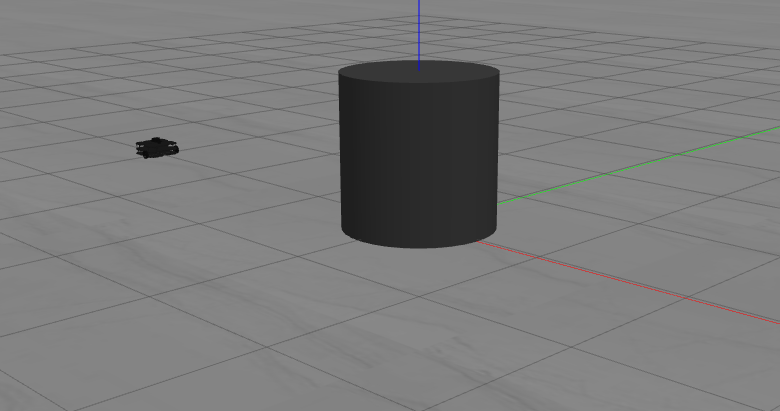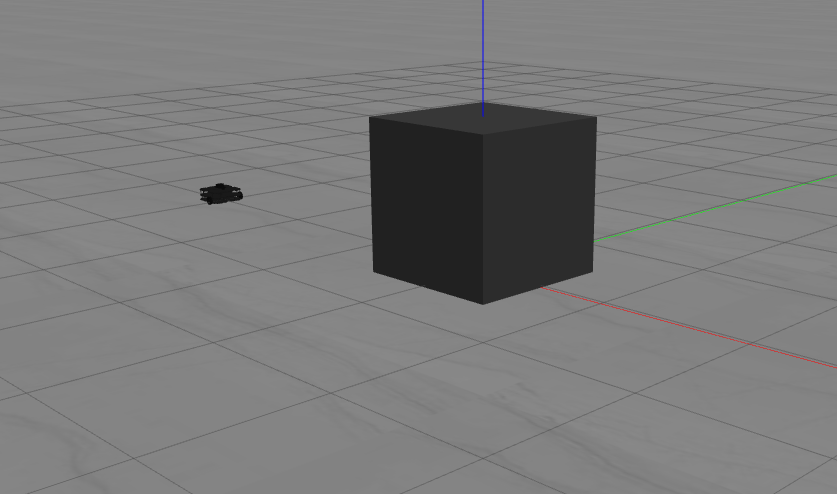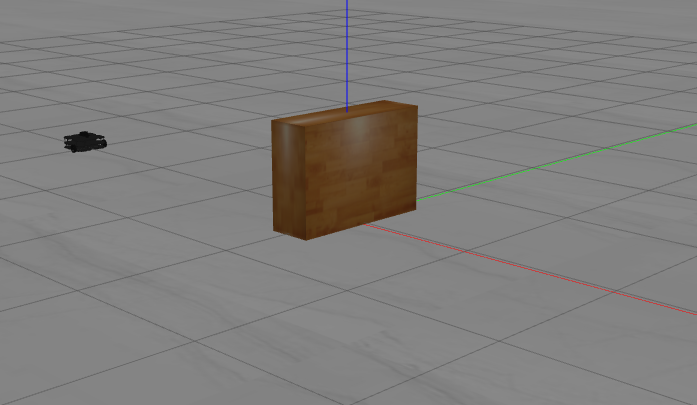

## Simulación 1_Robot

- Mapa de 10x10 mts

Tiempo de Simulación:

% setup enviroment 
clear, clc, close all
% Variables de inicialización
t_sim=45;

Inicialice los puntos de interés o trayectoria del robot:

Ejemplo: Way=[0 0; x1 y1; ...; xn yn]

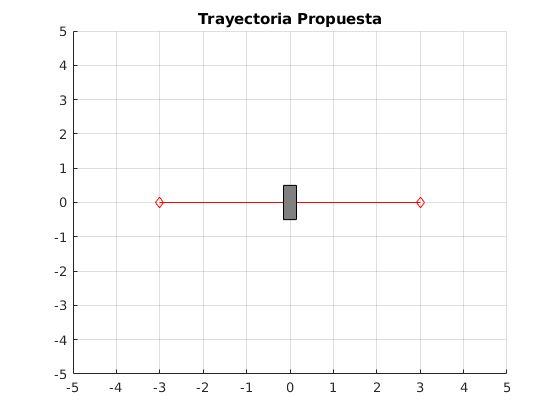

Way=[3 0; -3 0 ];

%%Inicialización controlador PurePursuit
PP=controllerPurePursuit;
PP.Waypoints=Way;
PP.MaxAngularVelocity=1.82; %rad/s 
PP.DesiredLinearVelocity=0.2;% m/s
PP.LookaheadDistance=0.5; %m 
%%Inicialización Algoritmo VFH
VFH = controllerVFH;
VFH.UseLidarScan=true;
VFH.NumAngularSectors=360;
VFH.DistanceLimits=[0.3, 3.5];
VFH.RobotRadius=0.22;
VFH.SafetyDistance=0.35;
VFH.MinTurningRadius=0.4;
VFH.HistogramThresholds=[5,10];

% grafica base
hold on
plot(Way(:,1),Way(:,2),'r-d');
xticks(-5:5)
yticks(-5:5)
grid on
xlim([-5,5])
ylim([-5,5])
title("Trayectoria Propuesta")
%%inserción obstaculos
select=3;

switch select
    case 1
        l=1;
        pos = [-l/2 -l/2 l l]; 
        rectangle('Position',pos,'FaceColor',[.5 .5 .5])
    case 2
        r=0.5;
        pos = [-r -r 2*r 2*r]; 
        rectangle('Position',pos,"Curvature",[1,1],'FaceColor',[.5 .5 .5])        
    case 3
        l=1;
        pos = [-0.15 -l/2 0.3 l]; 
        rectangle('Position',pos,'FaceColor',[.5 .5 .5])         
end
hold off

# Ejecutar Base_1Robot.slx

## Cargar Información de la simulación

Ejecutar al finalizar la ejecución del .slx

t=actuators1.time;
U1=actuators1.signals.values(:,1);
W1=actuators1.signals.values(:,2);
Lidar.angles=angles1.signals.values;
Lidar.ranges=ranges1.signals.values;
X=pose1.signals.values(:,1);
Y=pose1.signals.values(:,2);
YAW=pose1.signals.values(:,3);
TD=targetDir1.signals.values(1,:);
[it_max,~]=size(Lidar.ranges);
 
min(min(ranges1.signals.values))

ans = 0.6388

## Gráficas:

cte=4;

### Posición

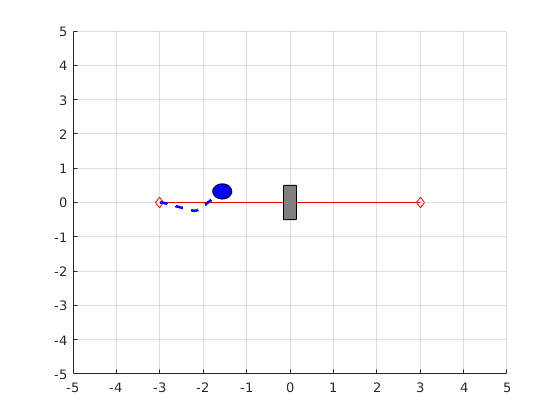

close
figure()
hold on
plot(Way(:,1),Way(:,2),'r-d');
xticks(-5:5)
%% Inserción Obstaculo
switch select
    case 1
        l=1;
        pos = [-l/2 -l/2 l l]; 
        rectangle('Position',pos,'FaceColor',[.5 .5 .5])
    case 2
        r=0.5;
        pos = [-r -r 2*r 2*r]; 
        rectangle('Position',pos,"Curvature",[1,1],'FaceColor',[.5 .5 .5])        
    case 3
        l=1;
        pos = [-0.15 -l/2 0.3 l]; 
        rectangle('Position',pos,'FaceColor',[.5 .5 .5])         
end

grid on
xlim([-5,5])
ylim([-5,5])
% title("Posición Robot1")
r=0.22;
pa=rectangle('Position',[-3-r 0-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'b',...
    'FaceColor','b');
plot(X(1),Y(1),'b--')
% legend("AutoUpdate","off")
% legend("Trayectoria Deseada","Trayectoria Real")
for i=1:length(X)/cte
%     plot(X(i),Y(i),'b>')
    r=0.22;
    pos = [X(i)-r Y(i)-r 2*r 2*r]; 
    delete(pa);
    plot(X(1:i),Y(1:i),'b--','LineWidth',2)
    pa=rectangle('Position',pos,'Curvature',[1 1],"EdgeColor",'k',...
    'FaceColor','b');
%     legend("Waypoints","Trayectoria Real")
    pause(0.1)
end 
hold off

### Velocidades

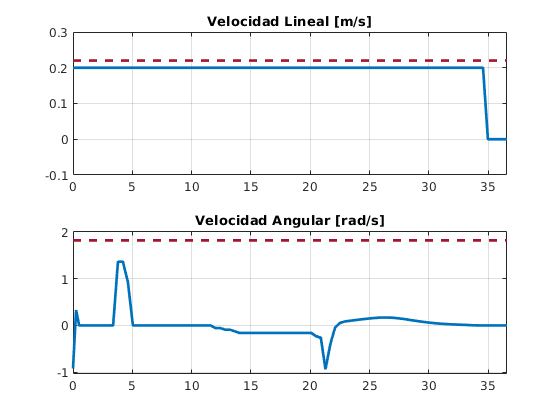

 
figure()
maxv=0.22;
maxw=1.82;
subplot(2,1,1)
hold on
l1=ones(1,length(t));
plot(t,U1,'LineWidth',2);
title("Velocidad Lineal [m/s]")
xlim([0,t(end)]);
ylim([min(U1)-0.1,max(U1)+0.1])

plot(t,maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t,-maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
grid on
box on
hold off
subplot(2,1,2)
hold on
plot(t,W1,'LineWidth',2);
plot(t,maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t,-maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
title("Velocidad Angular [rad/s]")
ylim([min(W1)-0.1,maxw+0.2])
xlim([0,t(end)]);
grid on
box on
hold off

### LIDAR:

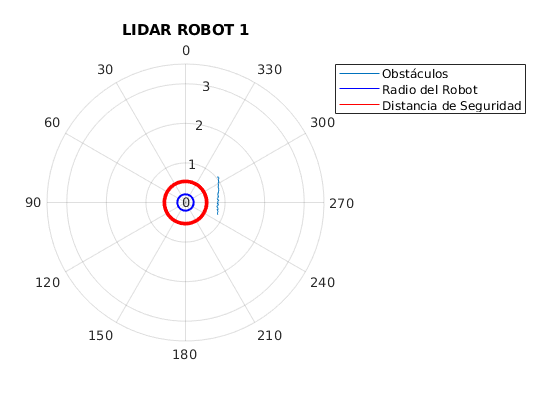

 
% rob=0.5*ones(1,it_max);
RR=VFH.RobotRadius*ones(1,360);
SD=VFH.SafetyDistance+RR;
theta=1:360;
figure
for i=1:it_max/cte
  polarplot(Lidar.angles(i,:),Lidar.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
%   annotation('arrow',[0.5244 0.562],[0.5007 0.5039])
  title("LIDAR ROBOT 1")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
  legend("Obstáculos","Radio del Robot","Distancia de Seguridad","Location","bestoutside")
  pause(0.1) 
end

### VFH (Vector Field Histogram):

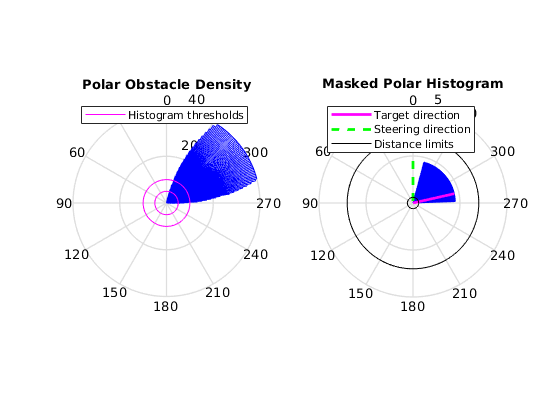

 
for i=1:it_max/cte
    scan=lidarScan(Lidar.ranges(i,:),Lidar.angles(i,:));
    targetDir =TD(i);
    steeringDir = VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end